# СКРИПТЫ И ФУНКЦИИ

## Семинар 5

### Работа с именами файлов и папками


disp("Current dir")
cd  % возвращает текущую (рабочую) папку 
pwd() % возвращает  рабочую папку
% при вызове с аргументом меняется рабочую папку
cd(get_folder()) % меняем рабочую папку 
% функция get_folder - возвращает путь к расположению файла кода, открытого
% в редакторе, этот путь может не совпадать с рабочей папкой
pwd()
temp_dir1 = fullfile(pwd(),"temp") % fullfile(folder1,folder2,...) генерирует строку пути к папке/файлу, в зависимости от операционной системы 
% ОС отличаюстя по формату пути , win - разделитель "/", unix - "\"
temp_dir2 = fullfile(".","temp") % относительный путь (оба варианта одинаковы)

% чистим папку если она существует
if isfolder(temp_dir1)
    rmdir(temp_dir1) % команда удаления папки
end

% создаем папку если ее не существует
if ~isfolder(temp_dir1)
    mkdir(temp_dir2) % команда создания папки
end

% Двигаемся вверх по дереву папок
 
cd .. % если при вызове функциии не указываются круглые скобки, 
% то входной аргумент интерпретируется как массив символов
pwd()

fullfile(temp_dir2) % относительный путь перестал работать
pwd()

cd(temp_dir1) % абсолютный путь
pwd()

% Создаем текстовые файлы
N=100
parfor ii=1:N
    fname = string(ii)+".txt";
    writematrix(rand(N),fname);% заполняем файл 
end

% находим файлы в папке при помощи функции dir()
dir_structure = dir(".") % возвращаем все файлы в текущей папке
file_names = string( ...
    {dir_structure(:).name} ... % splat функция, list-comprehention {struct(:).field}, 
    ...% [struct(:).field] тоже работает если содержимое поле может складываться в массив
    )'
full_file_names = fullfile(string({dir_structure(:).folder})',file_names);
is_file_Flag = ~[dir_structure(:).isdir]
average_value=0
for f=full_file_names(is_file_Flag)'
    average_value = average_value + sum(readmatrix(f),'all')/(N*N);
end
average_value = average_value/sum(is_file_Flag);
average_value

% альтернативный вариант - использовать ls
files_in_dir = ls("*.txt") % возвращает результат в виде матрицы символов, строка соответсвует имени файла, а количество
% столбцов максимальной длине (лишнее заполняется пробелами)
file_names2 = strip([string(files_in_dir(:,1:7))]) 

% можно заархивировать 
zip("../temp_zip",file_names2)    


### Workspace

#### Текущий "срез" памяти, показывает соотнесение между созданными пользователем данными и именами в настоящий момент времени (run-time)

#### Workspace -  пространство имен, в котором матлаб ищет символы в первую очередь, когда мы вводим имя переменной в командной строке

var1 = 15;
var2 = "вторая переменная"
A = 45;
whos % переменные в workspace
whos t* % все переменные, начинающиеся с t
whos *dir*

Получение информации о текущем **workspace** в процесее выполнения кода

who % возвращает имена переменных в текущем воркспейсе
what(get_folder()) % возвращает имена матлабовских функций в папке
what .. %  (".." - в данном случае - имя папки)


#### Удаление переменных из текущего **workspace**

A = 1;B = 15;
who
clearvars -except B % удаляме все кроме B
who

AC = 1;AB = 15;B = 15;
who
clearvars A* % можно также использовать regexp
who
exist B var % наличие переменной с заданным именем в воркспейсе можно проверять функцией exist

Когда вы вводим в командной строке символ, он ищется в первую очередь в текущем **workspace**

sin - встроеная функция для расчета синуса, pi  - встроенная константа матлаб

clearvars
sin(pi) 

sin="Eating pie is a sin, sin of pi is " + string(sin(pi))

Теперь sin - это строка символов (попробуйте дважды запустить этот блок)

sin(pi)

clearvars
sin(pi)

#### Сохранение переменных из текущего **workspace**

Матлаб имеет собственный бинарный формат файлов, который позволяет сохранять содержимое **workspace, **частично или полностью

A = 1;B = 15;
if ~isfolder(fullfile(get_folder(),"mat"))
    mkdir(fullfile(get_folder(),"mat"))
end
save("mat_file.mat") % mat - файл, бинарный файл для хранения матлабовский данных как есть
clearvars % почистили воркспейс
who
load("mat_file.mat","A"); % загрузили переменную А из файла 
who

Браузер текущего воркспейс

workspace

### Как (может быть) устроен MATLAB внутри?

**Не известно с момента появления JIT (Just In-Time compiler)**

**Язык программирования - это программа, которая переводит код из символьной формы, близкой к математической записи или человеческой речи, в машинный код**

Особенностью машинного кода является, в частности, то, что он требует типизации для формирования блоков команд, как это можно совместить с динамической типизацией?

Например, функция:

В матлабе записывается одинаково и для A и B типа **double** и для A и B типа **string**, однако, машинный код для этих операций будет совершенно разным. 

Откуда языку взять информацию про типы?

Елинственная возможность понять тип переменных  A и B  - это получить ее непосредственно в процессе работы программы (**run-time**), соответсвенно и машинный код должен быть либо сформирован заново в **run-time** , либо загружен из кэша (если такой сочетание типов уже вызывалось раньше, можно сохранить код в некоторм хранилище) и затем запущен. 

В результате при выполнении команды A + B будут "загружены/созданы" разные машинные коды при одинаковой симовльной записи кода  матлаб. 

Как преобразует код матлаб до конца не понятно, общее представление можно получить, если  посмотреть на то как с кодом работает другой язык динамической типизации **Julia** 

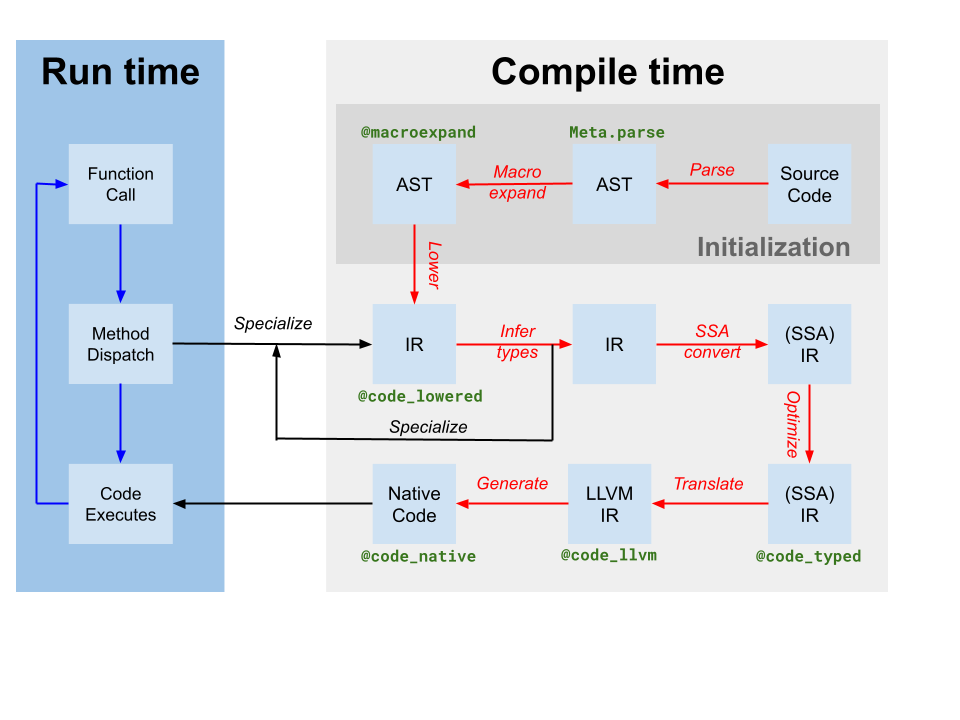

Основные этапы работы с кодом в **julia **на этой картинке следующие:

- **Парсинг**  - это преобразование исходных символов (**source code**) в некоторую промежуточную форму, которая называется **AST** (abstract syntax tree), в этой форме развернуты элементы синтактического сахара

- В **julia** дальше следует развертывание макросов, в матлабе, насколько я понимаю макросов нет (по крайней мере они не доступны), так или иначе, код пробразуется в некоторую промежуточную форму **IR **(intermediate representation),  в этой форме язык не знает про типы. Далее проиходит ряд специфических для **julia**  преобразований и оптимизаций кода

- Слева показана работа в **run-time** при вызове функции, вначале проиходит выбор метода **method dispatch, **то есть необходимо понять какой метод использовать, в **julia** выбор метода производится в зависимости от типа (типов) аргумента, в **матлабе** выбор метода производится по имени функции (и по типу первого аргумента, если это метод класса).

- И далее есть два пути стрелкой вниз показан путь для ситуации когда для функции с данным набором типов уже создан метод (хранится в кэше), если такой метод есть вызывается он. Стрелкой **specialize** показано, путь когда такая функций ранее не вызывалась, тогда мы идем по большому кругу, необходимо прогнать run-type типы данных через серию преобразований, чтобы получить в конце концов **native code** (что-то близкое к ассемблеру). Таким образом, информация о типах берется из текущих типов переменных, но **JIT **компилятор применяет информацию о типах не непосредственно на исходном коде в символьной записи, а уже на некоторйо промежуточной форме кода.

К сожалению, для матлаб такой схемы у меня нет, интересно было бы посмотреть как работает **JIT **в матлаб. 

### Функция eval

Парсинг и выполнение кода

eval("A+B") %

A=5;B=6;
eval("A+B")

A="A";B="B";
eval("A+B")

C = "Very important variable"
eval("C=rand(100)") % выполнение eval  - заменяет переменную

N = randi(500)
fun = @()eval("rand("+string(N)+")");% это анонимная функция, про них - дальше

disp("Вызов  функции через eval: ")
timeit(fun)
N_string = string(N);
disp("Вызов функции с аргументом, вычисляемым через  eval: ")
timeit(@()rand(eval(N_string)))
disp("Непосредственный вызов функции с числовым аргументом без eval: ")
timeit(@()rand(N))

Итого, как правило, eval  - медленнее, чем вызов функции непосредствено, кроме того, использование eval приводит к меньшей прозрачности кода (см. пример с заменой переменной)

## Выводы по семинару 5 

- Функции для работы с файловой системой **cd**() - поменять текущую директорию, **pwd**() - запросить текущуб папку

- **Workspace** - пространство имен переменных и соответсвующего им содержимого в памяти в текущий момент времени. Функции **who**()  - имена переменных, **whos**() - информация о переменных. При старте матлаб, комнадная строка работает с  базовым **workspace** - **base**

- Прежде, чем быть выполненным текст программы  преобразуется и оптимизируется, окончательно инструкции "железу" формируются когда понятна типизация переменных, которая получается в режиме **run-time. **Алгоритм работы JIT в матлаб толком не понятен (документации на него нет), поэтому лучше всего, если нужен  

## Семинар 6

### Скрипты

Скрипт - эвивалент **copy-paste** кода, который сохранен в отдельный файл, то есть ему присвоено имя 

Этот кусок кода выполняется в том **workspace, **в котором скрипт был вызван

% формируем текст скрипта
script1_text = ["A=12;";...
                "B=C+A;"] % пока не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
if ~isfolder(fullfile(get_folder(),"scripts"))
    mkdir(fullfile(get_folder(),"scripts"))
end
rmpath(fullfile(get_folder(),"scripts")); % что происходит на данной строчке объясняется потом
cd(get_folder())
script_file_name = fullfile(".","scripts","script1.m") % имя файла, в который сохраняется скрипт 
% пишем текст скрипта в файл
writelines(script1_text,script_file_name); % writelines - пишет массив строк в текстовый файл, предполагая, что каждый элемент - это отдельная строка

Работа скрипта при его запуске из рабочей папки, где лежит скрипт

cd(fullfile(get_folder(),"scripts")) % сделаем текущей папкой - папку, где лежит скрипт 
current_folder = pwd();
current_folder


clearvars % чистим base воркспейс
some_variable = [];
who
script1 

Почему возникает ошибка?

clearvars
who
C=15 % создаем переменную C
A = "Ваше мнение очень важно для нас!"
whos
script1
whos
A 

Очень неприятный побочный эффект! Скрипт подменил переменную А

Что быстрее скрипт или eval?

clear all % чистит все, в том числе скомпилированные файлы
cd(fullfile(get_folder(),"scripts")) 
script_to_test_text = "A=rand(100);B=eig(A);" 
% пишем текст скрипта в файл
writelines(script_to_test_text,"script_test.m"); 
disp(" script_test : "); tic 
for ii=1:10    script_test; end
script_mean_time_per_run = toc/10
disp(" Eval(script_text) : "); tic
for ii=1:50 eval(script_to_test_text); end
eval_mean_time_per_run = toc/10

clearvars
% вернемся в корневую папку ливскрипта 
cd(get_folder()) % теперь рабочая папке  - это папка, в которй лежит сам ливскрипт
current_folder = pwd();
current_folder
% выполним этот скрипт
script1
% ошибка! 
% Почему?

### MATLAB path 

Вызов скрипта по имени производится точно также как запрос содержимого переменной с тем же именем.

Когда мы вызываем скрипт по его имени, матлаб:

-  Ищет переменную с таким именем в текущем workspace

- Затем ищет файл с этим именем вначале в текущей папке (**pwd**(), чтобы ее посмотреть) 

- Далее он перебирает папки в MATLAB path, причем в той последовательности, в которой они там написаны (сверху-вниз)

% посмотреть текущий путь
path
folders1 = path();

Пути в **MATLAB path** хранятся в заданной последовательности 

Чтобы в этом убедится создадим два скрипта с одним именем, но разным содержимым:

% создаем два скрипта с одним именем 
script1_folder = fullfile(get_folder(),"scripts1");rmpath(script1_folder); % варнинг можно игнорировать
script2_folder = fullfile(get_folder(),"scripts2");rmpath(script2_folder); % 
% создаем два скрипта с одним именем, но в разных папках (код функции
% make_script можно посмотреть в конце данного скрипта)
make_script(script2_folder,"same_script","disp('Выполняется script из папки scripts2')")  
make_script(script1_folder,"same_script","disp('Выполняется script из папки scripts1')")
% оба скрипта имеют имя script

Добавим путь к первому скрипту в конец **MATLAB path**

folders = path()
folders= path(folders,char(script1_folder)); % доабавляет путь в конец 
same_script

Добавим путь ко первому скрипту в конец **MATLAB path**

folders = path(char(script2_folder),folders); % доабавляет путь в начало 
same_script

rmpath(char(script2_folder)) % удаляем путь ко второй папке со скриптом 
same_script % теперь опять запускается первый скрипт

% savepath()  сохраняет текущий набор путей в файл дефолтного набора путей,
% который загружаются при старте матлаба (не будем ее забивать)
savepath("cur_path.m") % сохраняет в отдельный файл

Графическая оболочка для редактирования путей

pathtool

### Функции

До этого момента мы работали в базовом  **workspace, **то есть том, который загружается при старте матлаб. Заполнение пространства имен происходило путем выполнения операции присвоения при помощи символа "=" как конструкция вида: "variable_name=variable_value". После заполнения **workspace **переменными мы могли оперировать значениями, которые привязаны к их именам, путем ввода инструкций либо в командной строке, либо при помощи скриптов. Инструкции записывались как комбинации символов. При этом символы, соответсвующие именам переменных, содержащимся в **workspace,  **автоматически (при парсинге символов, записывающих эти инструкции) интерпретировались как привязанное к ним содержимое. На примере скрипта подменяющего набор символов для встроенной функции **sin, **мы убедились, что присвоение того же имени новому значению переобозначает данный набор символов, затеняя в данном случае встроенную функцию.

Написание достаточно сложной программы требует создания большого числа переменных, поэтому, оставаясь в рамках одного и того же **workspace, **есть большая вероятность совершить "подмену" переменных (как это происходило в примере со сриптами и функцией **eval**), что приведет к неправильной работе программы. 

Выходом тут является использование синтаксических конструкий, которые позволяют изолировать  пространства имен переменных для различных составных частей программы друг от друга (само содержимое переменных, может при этом быть и не изолировано, но этот вопрос мы будем рассматривать в последующих семинарах для объектов особого типа **handle**). 

Основным  инструментом языка матлаб (и парадигмы функционального программирования), который позволяет создавать изолированное пространство имен являются функции. 

Таким образом, каждая функция имеет свой **workspace, **содержимое которого в момент начала выполнения кода функции определяется именами ее входных аргументов и привязанными к ним значениями ( но не всегда только ими, см. вложенные функции далее). Базовый синтаксис записи кода функций показан ниже:

Функции, как и скрипты могут быть записаны в текстовые файлы с расщирением "**.m**"

Когда происходит вызов функции, то есть, матлаб встречает языковую конструкцию вида "**function_name(...)**" для него это значит, что надо найти ее имя и код функции либо в **workspace**, либо в **matlab path**  и запустить его (об этом ему говорят круглые скобки). В круглых скобках после имени функции указываются имена аргументов (или непосредственно значения) соответсвующие переменным того **workspace, **из которого происходит вызов функции (**caller workspace**).

Воркспейс функции формируется в момент ее вызова. То есть, когда мы вызываем функцию, передавая в качестве аргументов имена переменных,  в  **workspace** функци добавляются переменные, имеющие значения,  соответсвующие именам переменных из **caller workspace, ** а имена, заданным в заголовке функции. В качестве аргументов могут выступать непосредственно значения (числа **double**, символы **string**/**char**, более сложные типы данных, такие как **struct**, **cell **и др.)

functions_folder = fullfile(get_folder(),"functions_folder")
if isfolder(functions_folder)
    rmpath(functions_folder) % удаляем из пути матлаб папку с функциями (физически она не удаляется)
end
make_function(functions_folder,... % folder 
                        "swap",... % function name 
                        ["A" "B"],...% input arguments
                        ["A" "B"],...% output arguments
                        "%Эта функция меняет местами переменные и отображает свой workspace",...
                        "C=A;A=B;B=C;",...
                        "disp('Содержимое workspace функции swap:')",...
                        "who % функция who ( и прочие функции работы с workspace) теперь будут работать в workspace это фукнции)")% function body
% буду иногда пользоваться самодельной функцией make_function, она генерирует код
% функции и текста (создает тектовый файл и пишет туда строки)
% функция read_code - по имени фукнции ищет файл с ней и считывает код
% функции

Сгенерированный make_function файл этой функции будет выглядить вот так (в этом можно убедиться открыв созданный файл в редакторе):

Вызов функции производится при помощи записи "function_name()", где function_name - имя вызываемой функции.

[A,B] = swap("A","B") % вызываем функцию при помощи оператора "()"

addpath(functions_folder);% добавляем папку в MATLAB path

read_code("swap") % самодельная функция, которая выводит код по имени функции

read_code("sin") % код встроенный функций как правило недоступен

clearvars -except functions_folder
[A,B] = swap("A","B") % работает
disp('Содержимое workspace base:')
who

help swap % выдает докстринг в консоль

doc swap % отображает его в браузере 


Можно игнорировать выходные аргументы (второй аргумент, возвращаемый функцией не присваивается к новой переменной)

clearvars -except functions_folder
[~,B] = swap("A","B") % выходные аргументы функции можно игнорировать
A = swap("A","B");
who

Функция может игнорировать входные аргументы 

ignore_arguments(9)
ignore_arguments(9,10)
ignore_arguments(9,10,12)

Зачем это нужно? 

Позволяет сохранить сигнатуру функции как трех-аргументной

% данная функция не имеет входных и выходных аргументов
make_function(functions_folder,... % folder 
                        "noargs",... % function name 
                        "",...% input arguments
                        "",...% output arguments
                        "disp('Содержимое workspace функции noargs:')",...
                        "who")

noargs()

read_code("noargs")

#### **Указатель на простую функцию**

 Иногда нужно передать функцию в качестве аргумента, для этого можно перед ее именем поставить знак "@" и она превратится в указатель на функцию

simple_fun_handle = @swap % указатель на функцию
class(simple_fun_handle) % относится к особому классу объектов
[A,B] = simple_fun_handle(1,2)

Указатели на функцию относятся к классу **function_handle**

class(simple_fun_handle) % особый тип объектов function_handle


Например код функции, которая вызывает другую функцию может выглядить так:

[A,B] = call_handle("A","B",simple_fun_handle)

% можно преобразовывать строки в указатели на функции
fun_handle = str2func("sin")

Массив указателей на функцию можно хранить в массиве ячеек:

% arrayfun - применяет указатель на функцию на каждом элементе массива,
% результат, который она возвращает пытается сложить в массив если вызвана
% с признаком ...,'UniformOutput',true), если ...,'UniformOutput',false) -
% то кажыдй результат вызова вкладывается в свою ячейку, таким образом, на
% выходе имеем массив ячеек размером со входной массив 
fun_handles_cell = arrayfun(@str2func,["sin" "cos" "svds"],'UniformOutput',false) % здесь приходится делать массив ячеек,
% так как указатели на функции нельзя складывать в один массив (не знаю
% почему)


Пример. вызов большого количества функций  в цикле

A = rand(5);
for f = fun_handles_cell
    disp("Функция с именем " + string(func2str(f{1})) + " дает :") % func2str - обратное к str2func действие 
    f{1}(A)
end

fun_handles_struct = arrayfun(@(X) struct("fun",str2func(X)),["sin" "cos" "svds"]) 

#### Метаданные из указателя на функцию

simple_fun_handle = @swap
functions(simple_fun_handle) % вытягивает метаинформацию из указателя на функцию
%  - name имя функции оригинала
%  - type тип функции simple/anonymous/nested 
%  - file
function_file_name = functions(@swap).file


#### **Анонимные функции - функции, не имеющие своего собственного файла - anonymous**

Тоже относятся к классу **function_handle**

 Нет файла, зато есть **workspace**, который формируется в момент создания функции из того **workspace**

В приведенном выше коде: 

- anonymous_function_handle - имя создаваемой функции

 -  ARG1,ARG2,ARG3 - символы, обозначенные как входные аргументы, 

-  (ARG1,ARG2,ARG3, WS_VAR1,WS_VAR2) - тело функции - код, в котором фигурируют  имена входных аргументов, а также имена переменных, имеющихся в текущем **workspace**

При интепретации кода анонимной функции для нее создается свой **workspace, **в который входят (с теми же именами) переменные WS_VAR1,WS_VAR2, то есть  переменные **workspace, **в котором происходится создание анонимной функции,  которые используются в ее коде. В момент создания анонимной функции создается "срез" того **workspace, **в котором она создаеся .

%пример 
anon_fun = @(f,x) ((f(x+10*eps)-f(x))/(10*eps))

sin_fun = @sin;
x = transpose(linspace(-pi,pi,100));

plot(x,anon_fun(sin_fun,x),x,sin_fun(x));
legend("mysterious function","sin")

clearvars -except anon_fun
f = @sin;% в текущем workspace "приписали" значение к символу "f"
anon_fun2 = @(x) ((f(x+10*eps)-f(x))/(10*eps));% создаем анонимную функцию, 
% в коде которой фигурирует переменная "f", но, в отличие от anon_fun, символ "f" 
% не обозначени как аргумент (так как его нет 

f=@cos; % в текущем workspace заменили значение, приписанное к символу "f"
anon_fun3 = @(x) ((f(x+10*eps)-f(x))/(10*eps)); % код этой функции точно такой же

Теперь у функций **anon_fun2** и **anon_fun3 **код одинаковый, а содержимое воркспейсов разное, так как  в них запечатлены разные "срезы" одного и того же воркспейса, но в разные моменты времени

x = transpose(linspace(-pi,pi,100));
anon_fun2(x) - anon_fun(@sin,x)
anon_fun3(x) - anon_fun(@cos,x)

class(anon_fun)
functions(anon_fun)

При создании анонимная функция копирует из **workspace**, в котором она создается, в свой  **workspace** те переменные, которые есть в ее коде.

В данном случае это переменная f - указатель на функцию


disp("anon_fun workspace:")
functions(anon_fun).workspace{1} % содержимое воркспейса анонимной функции
disp("anon_fun2 workspace:")
functions(anon_fun2).workspace{1} % содержимое воркспейса анонимной функции

Меняем код анонимной функции и создаем новую анонимную функцию из старой

anon_fun_code = functions(anon_fun).function; % код функции в виде строки
new_anon_fun_code = replace(anon_fun_code,"eps","1e-6");% replace- функция для работы 
% со строками - позволяет заменить последоватлеьность символов - другой, в
% данном случае заеняет "eps" в коде анонимной функции на "1e-6"
new_anon_fun = str2func(new_anon_fun_code)
new_anon_fun()

Как сделать так, чтобы сохранился workspace копируемой  функции?

Анонимные функции можно коневертировать в символьные 

% анонимые функции можно конвертировать в символьные (иногда получается
% криво)
sym_fun = sym(anon_fun2)

sym_fun_integral = sym(@(x)sin(x)) - int(sym_fun)

И обратно....

F = matlabFunction(sym_fun_integral,'Vars','x') % теперь это снова анонимая функция 

functions(F)
functions(F).workspace{1}

F(x)

Затеняем анонимной функцией встроенную

N=10;
zu = @(k,x) power(-1,k).*power(x,1+2*k)./(factorial(1+2*k))
sin = @(x) sum(zu(0:N,x))

sin(3) % затеняем встроенную функцию
builtin('sin',3) % функция builtin позволяет вызвать встроенную функцию даже когда она затенена в данном workspace

simple_optimizer(0.1,@cos,anon_fun)

### Полезные штуки для функций 

#### **Произвольное число входных аргументов - *****varargin*** 

#### **Как узнать число входных аргуметов, находясь внутри функции - *****nargin*** 

make_function(functions_folder,... % folder 
                        "vararargin_function",... % function name 
                        "A,B,varargin",...% input arguments
                        "out",...% output arguments
                        "out = A+B;",...
                        "disp('nargin =>' + string(nargin));",...
                        "disp('numel(varargin) =>' + string(numel(varargin)));",...
                        "for v=varargin","out = out + v{1};","end")

vararargin_function(10,20)
vararargin_function(10,20,40,78,149)
vararargin_function("a","b","c")

#### **Произвольное число вЫходных аргументов  - *****varargin***

#### **Как узнать число выходных аргументов, находясь внутри функции - *****nargout***

#### **Как прерывать выполнение функции - *****return*** 

[A,B] = vararargout_function(rand(100))

[A,B] = vararargout_function(rand(100),rand(100))

[A,~] = vararargout_function(rand(100),rand(100)) % тильда внутри функции считается за аргумент

[~,B] = vararargout_function(rand(100),rand(100),rand(100))

disp("Один входной аргумент, один выходной: " + string(timeit(@()vararargout_function(rand(500)),1)))

disp("один входной аргумент, два выходных: " + string(timeit(@()vararargout_function(rand(500)),2)))

disp("два входных, два выходных: " + string(timeit(@()vararargout_function(rand(500),rand(500)),2)))

disp("три входных, два выходных: " + string(timeit(@()vararargout_function(rand(500),rand(500),rand(500)),2)))

Так как воркспейс функции - это точно такой же воркспейс как и базовый, внутри функций можно применять методы для работы с воркспейсом, которые обсуждали ранее

Для примера можно использовать функцию exist (хотя есть более прозрачные способы гарантировать существование переменных)

help exist

exist_check_fun(9)
exist_check_fun(9,15)
exist_check_fun(9,15,16)

Поменяем содержимое файла функции **swap**

уберем из функции swap disp и who

% уберем из функции swap disp и who
functions_folder = fullfile(get_folder(),"functions_folder");
make_function(functions_folder,... % folder 
                        "swap",... % function name 
                        ["A" "B"],...% input arguments
                        ["A" "B"],...% output arguments
                        "C=A;A=B;B=C;")% function body
addpath(functions_folder)

[A,B] = swap("A","B")

#### Вложенные (nested) функции

Вложенные функции - это функции декларированные в теле функции. 

Для них доступен воркспейс внешней функции, аргументы вложенной функции могут "затенять"  аргументы внешней функции

[A,B,nested_fun_handle] = external_fun("A","B") % работает! 

Третий вид function_handle : nested

functions(nested_fun_handle)
% похоже на анонимную функцию, так как в ее воркспейспе сохраняется
% воркпейс внешней функции, окружение, в котором она должна работать

Мультивложенная функция

[A,B] = multi_embedded_fun("A","B") % работает! 

- Поставим breakpoint  в редакторе кода функции swap 

- Вызвать в командной строке матлаба функцию dbstack() -

- Подивиться на стэк!

timeit(@()swap("A","B"))
timeit(@()external_fun("A","B"))
timeit(@()multi_embedded_fun("A","B"))

В одном файле может быть несколько не вложенных функций

B = two_fun_one_file("A")

#### Перемещение по стэку!

Выполнить функцию eval()  в чужом воркспейсе  -  evalin(workspace, expression) % workspace  может быть либо 'base' - базовый workspace, либо 

help evalin

`Как сломать функцию`

`Вторая функция имеет вид:`

C = input_expression("rand(10)")

Присвоить перемнной заданного workspace значение, рассчитанное в данном воркспейс assignin(workspace,variable_name,value)

clearvars
assignin("base","newVar",whos)
newVar

Воркспейс функции после ее выполнения чистится, соответственно все переменные, которые не были возвращены вызывающей функции ('caller' вниз по стеку) будут стерты из памяти

on_clean_up_check("disp('Начало работы')", @()disp('Очистка '))

on_clean_up_check("'", @()disp('Очистка ')) % функция onCleanup работает когда в коде ошибка!

Рекомендуется всегда при работе при помощи функций с портами и низкоуровневыми функциями для записи в файл использовать 

#### Хранение данных в памяти функции - **persistent**

По умолчанию, после выполнения кода функции, ее воркспейс чистится из памяти, но можно сделать так , чтобы чистился не полностью, это позволяет при последующих запусках функции уже иметь в ее **workspace**  переменные, созданные при ее предыдущих вызовах, для этого в коде функции надо обозначить переменные аннотацией persistent.

dx = 0.1;
f = @sin;
for a=1:50
    persistent_func(f,dx); % в качестве аргументов в функцию передается только функция и величина шага, значение координаты (x в коде функции) остается с предыдущего вызова 
    pause(0.2) % ждем пол секунды
end

clear persistent_func % содержимое persistent переменных чистится при помощи функции clear имя_функции или clear('имя функции')

persistent_func(f,dx) % опять стартуем с нулевой координаты 

### Аннотация типов входных аргументов - блок arguments...end

Несмотря на то, что матлаб не требует объявления типов переменных (динамическая типизация) при написании функций, особенно тех, которые являются интерфейсом взаимодействия с "внешним миром", возникает необходимость создания большого числа проверок аргументов функций, чтобы избежать непредсказуемого поведения. Проверять приходится типы, размерность, принадлежность к определенному диапазону или набору значений и т.п.

В современном матлаб это можно делать при помощи блока **arguments...end**

Общие правила 

`arguments`

    `argName1 (dimensions) class {validators} = defaultValue`

`    ...`

    `argNameN ...`

`end`

out = annotated_arguments(1.3,rand([10,2]),"ghj")

out = annotated_arguments(3,rand([10,2]),"ghj")

out = annotated_arguments(3,rand([10,1]),"ghj")

out = annotated_arguments(3,rand([10,1]),"sin")

out = annotated_arguments(3,linspace(-pi,pi,100),"cos")

livescript_helper= functions(@annotated_arguments).file


#### **Использование блока arguments для создания аргументов типа name-value pair**

cd(get_folder)

name_value_pairs("A",5)

#### **Использование блока arguments для создание произвольного числа аргументов типа name-value pair**

repeating_name_value_pairs("A",35)
repeating_name_value_pairs("A",35,"b",67)
repeating_name_value_pairs("A",35,"b",67,"C",78)

#### BONUS. Пишем простой оптимизатор методами функционального программирования

 Что такое градиент функции:

$f(\vec{x})$ - скалярная функция векторного аргумента, где $\vec{x} \in R^n$

тогда градиент этой функции :


$$\nabla f(\vec{x})=\matrix {\frac{\partial f}{\partial x_1} \cr \vdots \cr \frac{\partial f}{\partial x_n} }$$


Если градиент как веткор в пространстве $R^n$ , то это вектор, который указывает в сторону наибольшего возрастания функции $f(\vec{x})$ . 

Функция численного расчета для расчета градиента произвольной функции может иметь следующий код (по аналогии с численным расчетом производной выше):

Градиентный оптимизатор - это итерационный алгоритм, который движется в пространстве $R^n$ от точке к точке в направлении, противоположном направлению градиента (направлению максимального возрастания), то есть, ($i+1$) координата в пространстве  $R^n$ выражается через предыдущую точку и градиент функции в виде:

$\vec{x}_{i+1} = \vec{x}_{i} -\mu\frac {\nabla f(\vec{x}_i)}{||\nabla f(\vec{x}_i)||}$,

$\mu$- скалярный параметры алгоритма, который фиксирован, конструкция $\frac {\nabla f(\vec{x}_i)}{||\nabla f(\vec{x}_i)||}$ фактически оставляет от градиента только направление. Код простого оптимизатора показан ниже:

function [x,Fval,ii,flag,search_history]=grad_search(x0,F,gradF,options)
% простой оптимизатор методом градиентного поиска
% входные аргументы:
%                   x0 - стартовая точка
%                   F - указатель на скалярную функцию векторного аргумента

gradF = function_handle with value:
    @(X)num_grad(F,X)


%                   gradF - указатель на функцию расчета градиента функции

xval = -1.5640

fval = -1.0000

iternumber = 565

outflag = 1×2 logical array
   1   1


%                           F

ans = -0.4978

%                   Опциональные аргументы в формате имя-значение
%                   mu (optional)- амплитудный коэффициент, длина шага 
%                   N (optional)- ограничение на число итераций
%                   tol (optional)- точность (относительное изменение для
%                   двух последовательных итераций)
% выходные аргументы:
%                   x - оптимальное значение вектора параметров оптимизации
%                   (минимизатор)
%                   Fval - значение функции для найденного минимизатора
%                   ii - число вычислений функции и ее градиента

gradF = function_handle with value:
    @(X)num_grad(F,X)


%                   flag - флажок критериев сходимости
%                   search_history - матрица, у которой столбцы -
%                   координаты в пространстве оптимизации, по которым ходил

xval =     0.0999
    0.6696


fval = 6.6436e-05

iternumber = 1000

outflag = 1×2 logical array
   1   1


%                   алгоритм
%                   
    arguments
        x0 double

xval =     0.1224
    0.6408


search_history =     0.3000    0.2891    0.2777    0.2664    0.2547    0.2419    0.2495    0.2367    0.2444    0.2322    0.2394    0.2269    0.2349    0.2223    0.2304    0.2185    0.2261    0.2142    0.2225    0.2101    0.2185    0.2061    0.2146    0.2023    0.2103    0.1986    0.2072    0.1951    0.2032    0.1911    0.1999    0.1877    0.1960    0.1839    0.1923    0.1802    0.1886    0.1771    0.1857    0.1738    0.1824    0.1710    0.1803    0.1689    0.1777    0.1664    0.1753    0.1640    0.1728    0.1611
    1.0000    0.9248    0.8496    0.7745    0.6994    0.6245    0.7001    0.6252    0.7008    0.6258    0.7014    0.6265    0.7021    0.6271    0.7027    0.6276    0.7032    0.6282    0.7037    0.6287    0.7043    0.6293    0.7048    0.6298    0.7054    0.6303    0.7058    0.6308    0.7063    0.6313    0.7068    0.6318    0.7073    0.6323    0.7078    0.6328    0.7083    0.6332    0.7087    0.6337    0.7092    0.6340    0.7095    0.6343    0.7098    0.6347    0.7101    0.6350  

        F function_handle
        gradF function_handle

fig1


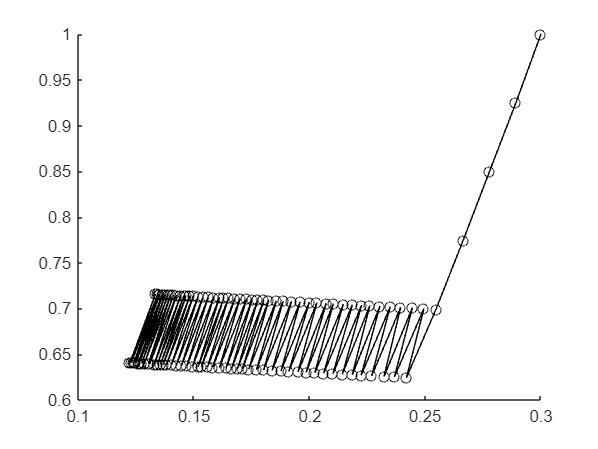

        options.mu (1,1) double =1e-2
        options.N (1,1) double =10000
        options.tol (1,1)double =1e-6
    end
    ii=1;

    x=x0(:);mu = options.mu;N = options.N;tol = options.tol;
    flag=[true true];
    Fval=F(x0);
    is_return_search_history = false;
    if nargout==5 % так как хранение всех точек может быть тяжелым

xval =     0.1016
    0.6697


fval = 8.8666e-06

iternumber = 20

outflag = 1×2 logical array
   0   1


search_history =          0    0.1481    0.2962    0.0070    0.1474    0.0759    0.1123    0.0945    0.1032    0.1075    0.0988    0.1032    0.1009    0.1021    0.1014    0.1017    0.1018    0.1016    0.1017    0.1016
         0    0.9890    1.9780   -0.0010    0.9891    0.4942    0.7415    0.6178    0.6797    0.7107    0.6488    0.6797    0.6643    0.6720    0.6681    0.6701    0.6710    0.6691    0.6701    0.6696


        is_return_search_history =true;% если число выходных аргументов равно пяти, то значит нужно сохранить историю
        search_history = NaN(numel(x),N);% резервируем память под все точки алгоритма
        search_history(:,1) = x0;

fig3


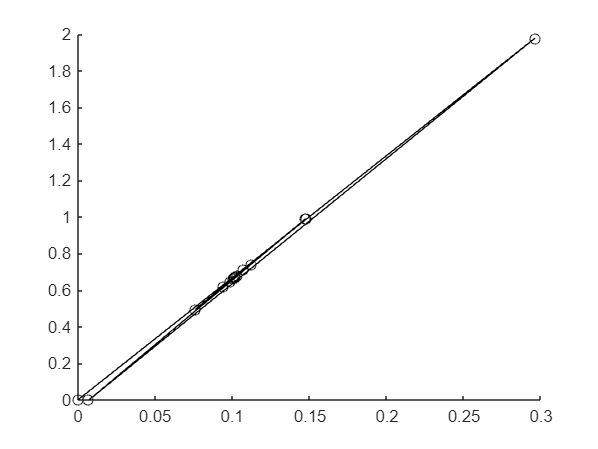

    end
    while ii<N && all(flag) % условием остановки служит достидение заданного числа итераций и проверка сходимости
        x_previous=x;F_previous = Fval; % значения коордианты и функции на предыдущей итерации
        grad_value = gradF(x); % рассчитываем градиент функции
        if norm(grad_value)==0

            return
        end

x =     0.1003
    0.6699


Fval = 2.5291e-06

ii = 71

flag = 1×2 logical array
   0   0


        grad_direction = grad_value/norm(grad_value); % используем только направление градиента
        x= x - mu*grad_direction(:);% рассчитываем координату для следующей точки
        Fval=F(x); % рассчитываем значение функции для этой координаты
        if is_return_search_history
            search_history(:,ii+1) = x;% если нужны промежуточные точки - добавляем
        end
        % флажок проверки сходимости
        flag = [norm(Fval-F_previous)>tol ...%  изменение значения функции
            norm(x_previous-x)>tol]; %  изменение координаты
        ii=ii+1; 
    end
    if is_return_search_history
        search_history = search_history(:,1:ii);
    end
end

    Следует отметить, что функция ***num_grad,*** в отличие от*** grad_search ***не имеет блока ***arguments...end***, это связано с тем, что так как она является частью итерационного алгоритма ее вызов производится большое количество раз, поэтому она не имеет функция для валидации аргументов. То есть, в данном случае мы следует правилу выполнять проверки "на входе", в данном случае входом являются входные аргументы функции  ***grad_search*****.**

Посмотрим как можно применять данные функции, вначале для одномерного поиска минимума скалярной функции:

F = @(x)sin(x);
gradF = @(X) num_grad(F,X) % численный расчет градиента
[xval,fval,iternumber,outflag]=grad_search(-1,F,gradF,"mu",0.001)
xval/pi


Теперь решим задачу векторной оптимизации - будем минимизировать квадратичную невязку между измеренными значениями и рассчитанными:


$$F(\vec{x})= \Sigma_k (y_i - f_i(\vec{x}))^2$$


$f_i(\vec{x})=x_1+x_2t_i$, где $t_i = [0:10]$

points = linspace(0,10,10)';
measured_points = 0.1 + 0.67*points;
F = @(x)sum(((x(1) + x(2)*points) - measured_points).^2); % воркпейс функции F содержит и экспериментальные и измеренные точки
gradF = @(X) num_grad(F,X) % численный расчет градиента, воркспейс функции gradF содержит и саму функцию F

% запускаем оптимизатор
[xval,fval,iternumber,outflag]=grad_search([0.0 0.0],F,gradF,"mu",0.001,"N",1000)

% сделаем еще прогон, чтобы посмотреть как алгоритм ставит точки
mu=0.076;
[xval,~,~,~,search_history]=grad_search([0.3 1],F,gradF,"mu",mu,"N",100)
% построим анимацию шагов работы алгоритма
animated_Line = animatedline(get_next_ax(),Marker="o",LineStyle="-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.1)
end

Интересно поварьировать величину шага !

В данном случая алгоритм на каждом шаге идет фактически в одном и том же направлении. Причина тут в том, что функция  является линейной относительно переменных оптимизации, то есть, направление градиента остается постоянным, значит не было необходимости считать градиент на каждой итерации. Алгоритм оптимизатора можно модифицировать так, чтобы после расчета направления градиента, если происходит уменьшение значения, он продолжал искать оптимальное решение в том же направлени, подобная стратегия называется линейным поиском:

[xval,fval,iternumber,outflag,search_history]=grad_search_linesearch([0.0 0.0],F,gradF,"mu",1,"N",1000)

% построим анимацию шагов работы алгоритма
animated_Line = animatedline(get_next_ax(),Marker="o",LineStyle="-");
for ii=1:size(search_history,2)
    v = search_history(:,ii);
    addpoints(animated_Line,v(1),v(2))
    pause(0.1)
end

[x,Fval,ii,flag]=grad_search_linesearch_numeric([0.0 0.0],F,gradF,"mu",1,"N",1000)



function folder = get_folder()
% функция смотрит какой файл открыт в редакторе в настоящий момент и
% возвращает путь к данному файлу
    folder = fileparts(matlab.desktop.editor.getActiveFilename);
end
function make_script(folder,name,varargin)
% функция создает текст скриптов и пишетего в файл
    arguments
        folder (1,1) string
        name (1,1) string
    end
    arguments (Repeating)
        varargin string
    end
    % формируем текст скрипта
        script1_text = string(varargin); % не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
        if ~isfolder(folder)
            mkdir(folder)
        end
        % пишем текст скрипта в файл
        writelines(script1_text,fullfile(folder,name + ".m"));
end
function make_function(folder,name,input_args,output_args,varargin)
% функция создает текст функции и пишет его в файл
    arguments
        folder (1,1) string
        name (1,1) string
        input_args string
        output_args string
    end
    arguments (Repeating)
        varargin string
    end
    argin = cell(1,2+ numel(varargin));
    head = "function ";
    if ~isempty(output_args)
        head = head + "[" + join(output_args,",") + "] = ";
    end
    head =head + name;
    if isempty(input_args)
        head = head +"()";
    else
        head = head +"(" + join(input_args,",")+")";
    end
    argin{1} = head;
    argin(2:end-1) = varargin;
    argin{end} = "end";
    % формируем текст скрипта
    fun_text = string(argin); % не будем пользоваться матлабовским редактором файлов, так как он "слишком умный"
    if ~isfolder(folder)
        mkdir(folder)
    end
    % пишем текст скрипта в файл
    writelines(fun_text,fullfile(folder,name + ".m"));
end
function code = read_code(fun_name)
    switch class(fun_name)
        case "string"
            filename = functions(str2func(fun_name)).file;
        case "function_handle"
            filename = functions(fun_name).file;
        otherwise
            code = '';
            return
    end
    if isempty(filename)
        code = fun_name;
        return 
    end
    code = string(fileread(filename));
end
function varargout = vararargout_function(varargin)
    % varargout  - тоже особое слово, в теле функции оно означает, что
    % данный массив ячеек возвращается как splat - функции
    disp(['Число входных аргументов: ' num2str(nargin)]);
    disp(['Число вЫходных аргументов: ' num2str(nargout)]);
    
    number_output_arguments = nargout; % особое слово, чтобы узнать число выходных аргументов, находясь фнутри функции
    varargout = cell(1,number_output_arguments);
    for counter=1:numel(varargin)
        if counter>number_output_arguments
            return
        else
            varargout{counter}=svds(varargin{counter});
        end
    end       
end
function out = ignore_arguments(x,~,~)
    out = sin(x);
end
function no_ignore_arguments(x,y,z) % аргументы фигурируют, но не игнорируются
    out = sin(x);
end
function [A,B] = call_handle(A,B,fun_handle)
    [A,B] = fun_handle(A,B);
end
function [A,B,nested_fun_handle] = external_fun(A,B)
     who
    nested_fun() % вызов вложенной функции (может быть в любом месте, вложенная функция - не скрипт!
    function nested_fun() % объявление вложенной функции
        disp("workspace вложенной функции")
        who % почему не работает второй ху?
        [A,B] = swap(A,B); % переменные во внешней функции для вложенной функции являются глобальными
    end
    nested_fun_handle = @nested_fun;
end
function [A,B] =multi_embedded_fun(A,B)
    embedded_fun()
    function embedded_fun()
        embedded_fun()
        function embedded_fun()
            embedded_fun()
            function embedded_fun()
                embedded_fun()
                function embedded_fun()
                    embedded_fun()
                    function embedded_fun()
                        embedded_fun()
                        function embedded_fun()
                            who
                            [A,B] = swap(A,B);
                        end 
                    end 
                end 
            end 
        end 
    end 
end
function out = annotated_arguments(A,B,C)
    arguments 
        A (1,1) {mustBeInteger,mustBePositive} % означает, что аргументы должен быть целым
        B (1,:) double % дополнительно указан тип аргумента, также размерность указана частично!
        C (1,1) string {mustBeMember(C,["sin" "cos" "tan"])} ="sin" % 
    end
    out = repmat(transpose(B),[1 A]);
    fun_handle = str2func(C);
    for i = 2:A
        out(:,i) = fun_handle(out(:,i-1));
    end
end
% function out = name_value_pairs(options)
% % Важно при написании функций делать к ним хорошую документацию. 
% % Блок arguments можно рассматривать как часть документации, так как информация о типах, 
% % структуре и области определения входных аргументов функции многое говорит о функции
%     arguments 
%         options.A (1,1) {mustBeInteger,mustBePositive} = 3 % означает, что аргументы должен быть целым
%         options.B (1,:) double = linspace(-pi,pi,100) % дополнительно указан тип аргумента, также размерность указана частично!
%         options.C (1,1) string {mustBeMember(options.C,["sin" "cos" "tan"])} ="sin" % 
%     end
%     out = repmat(transpose(options.B),[1 options.A]);
%     fun_handle = str2func(options.C);
%     for i = 1:A
%         out = fun_handle(out);
%     end
% end
function C = input_expression(expression)
    C = eval(expression);
    whos
    caller_killer()
    whos 
end
function caller_killer()
    evalin('caller','clearvars');
end

function C = assign_in_function(expression)
    C = eval(expression);
    whos
    assignin_internal_fun()
    whos 
end
function assignin_internal_fun()
    evalin('caller','C=pi');
end
function [y,p] = persistent_func(f,dx)
% функция сдвигает фазу аргумента функции f на величину dx
    persistent x
    persistent animated_Line axes_handle; % при первом пуске persistent переменная []
    if isempty(x)
        x =-dx; % обнуляем сдвиг в начальный момент
    end
    if isempty(animated_Line)
        axes_handle = axes(figure(10),"XTickMode","manual","YTickMode","manual","XLim",[0,2*pi],"YLim",[-1 1]);
        animated_Line = animatedline(axes_handle,"Marker","o","LineStyle","none");
    end
    x=x+dx;
    y = f(x);
    addpoints(animated_Line,x,y);
    drawnow  
end
function out = repeating_name_value_pairs(name,value)
% Важно при написании функций делать к ним хорошую документацию. 
% Блок arguments можно рассматривать как часть документации, так как информация о типах, 
% структуре и области определения входных аргументов функции многое говорит о функции
    arguments (Repeating)
        name (1,1) string  % означает, что аргументы должен быть целым
        value (1,:) double  % дополнительно указан тип аргумента, также размерность указана частично!
    end
    out = cellstr(name) + "=" + string(cell2mat(value));
end
function out = exist_check_fun(A,B,C)
% функция exist(variable_name,"var") проверяет существует ли переменная с именем variable_name
out = 0;
    if exist('A','var')
            out = out + A;
    end
    if exist('B','var')
            out = out + B;
    end
    if exist('C','var')
            out = out + C;
    end
end
function on_clean_up_check(expr,f_handle)
    on_clean_up_obj = onCleanup(f_handle);
    eval(expr);
    pause(5)
    
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end